# Cancer cell line metabolic perturbation for different nutrient sources

## Initialize the model and load relevant datasets / lists

The following reactions were turned off (lower bound and upper bound are set to 0) for the flux analysis: ALR, MGSA, and MGSA2. The default constraints for the modified iMAT algroithm with the PROM lower bound constraint were used.

clear all;
initCobraToolbox; changeCobraSolver('gurobi', 'all');



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2020
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.25.4).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

% Load eGEM. Re-scale default upper and lower bounds to have smaller solution
% space.
load 05042020eGEM.mat; model = eGEM;

% Turn off reactions that negatively affect model performance.
posToTurnOff = find(ismember(model.rxns, {'ALR', 'MGSA', 'MGSA2'}));
model.ub(posToTurnOff) = 0; model.lb(posToTurnOff) = 0;

% Change the primary objective function
model.c = zeros(size(model.c));
%OBJ = find(ismember(model.rxns, 'ATP_objective'));    model.c(OBJ) = 1;
%OBJ = find(ismember(model.rxns, 'NADPH_objective'));  model.c(OBJ) = 1;
OBJ = find(ismember(model.rxns, 'biomass_objective')); model.c(OBJ) = 1;

## Compute the metabolic fluxes with metabolic perturbation for CCLs with the TCGA-110 cell line panel

First, we'll ge the cancer cell lines that intersect between the CCLE and the TCGA-110 panel.

load mediumPerturbation.mat mediumPerturbationIDs
load meta.mat meta
load zeta_sra.mat

% Get matching TCGA-110 to CCLE
testCCL = string(readcell('TCGA110.csv', 'FileType', 'text'));
CCLs    = testCCL(2:end, 1);
[~, ~, idx] = intersect(string(meta.CellLine), CCLs);
CCLs = CCLs(idx);
medium = meta.Media(idx);
medium = strrep(medium, ' ', '');
medium = strrep(medium, '-', '');

histoneReactionPositions = [3755, 3756, 3757, 3758];

## Compute metabolic perturbation for TCGA-110 cancer cell lines 

Next, compute the metabolic fluxes from medium perturbation using the `perturbMedium` function. The differentially expressed genes and the constrained model were computed using the `constrainMetabolicModel` function.

% Compute metabolic perturbation
%parpool(4);
constrainedModel = model;
hyperparams.eps = [];  hyperparams.kap  = [];
hyperparams.rho  = []; hyperparams.mode = true;
hyperparams.eps2 = []; hyperparams.pfba = true;
hyperparams.kap2 = [];

## Compute metabolic perturbation data

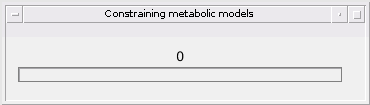

wtbr = waitbar(0, '0', 'Name', 'Constraining metabolic models');                          % Create waitbar

for i = 1:1
    mediumModel   = addMediumConstraints(constrainedModel, string(medium(i)));            % Add on medium constraints
    diffExpGenes  = findDiffExpGenes(mediumModel, string(CCLs(i)));                       % Find differentially expressed genes for this cancer cell line
    ON_fieldname  = string(strcat('ON_', string(CCLs(i))));                               % Make fieldnames for structure
    OFF_fieldname = string(strcat('OFF_', string(CCLs(i))));
    for j = 1:length(histoneReactionPositions)
        tmp_mdl = mediumModel;
        tmp_mdl.c(histoneReactionPositions(j)) = table2array(zeta(string(medium(i)), j));
        [ON_solution, OFF_solution] = perturbMedium(mediumModel, hyperparams, ...
                                                    mediumPerturbationIDs, ...         
                                                    diffExpGenes.(ON_fieldname), ...
                                                    diffExpGenes.(OFF_fieldname));
        hist_on(:, j)  = ON_solution.ONFluxes(: , histoneReactionPositions(j));
        hist_off(:, j) = OFF_solution.OFFluxes(:, histoneReactionPositions(j));
    end
    onSolutions{i, 1} = CCLs(i);  onSolutions{i,  2} = hist_on;                            % Store all supplementation metabolic fluxes
    offSolutions{i, 1} = CCLs(i); offSolutions{i, 2} = hist_off;                           % Store all deprivation metabolic fluxes
    
    waitbar(i/length(CCLs), wtbr, sprintf('%d', i))                                        % Update waitbar
end

## Save it all as a MATLAB variable

This code block saves the solutions as .mat files to be used later.

save('~/Data/CBM/eGEM/NutrientPerturbation/nutrientperturbation2.mat', 'onSolutions');
save('~/Data/CBM/eGEM/NutrientPerturbation/nutrientperturbation2.mat', '-append', 'offSolutions');